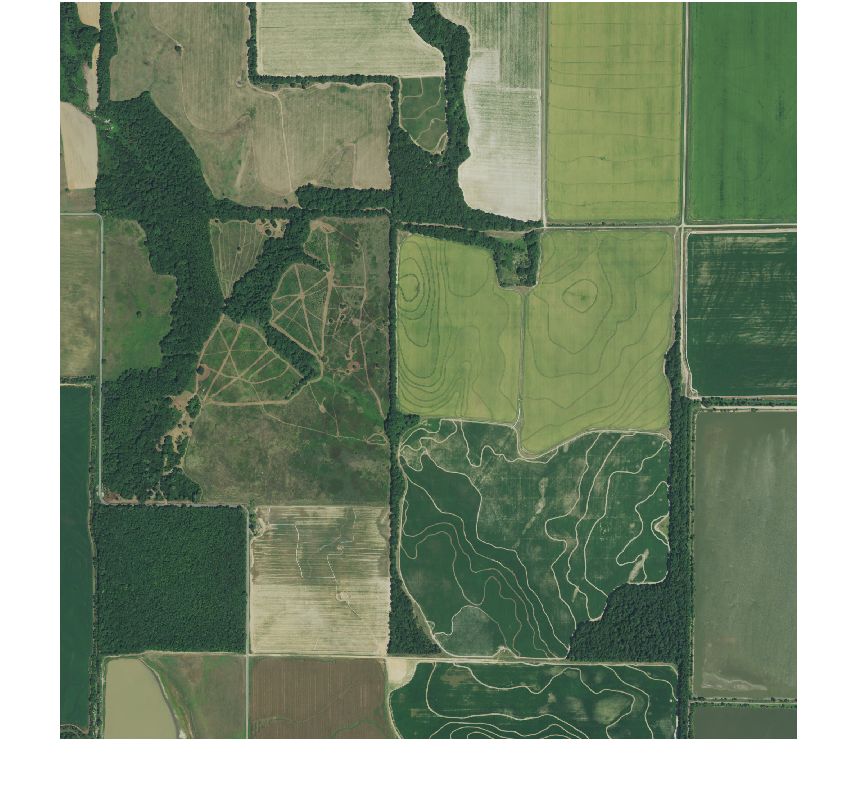

image = imread("L88b.jpg"); %Load the image
figure,imshow(image)

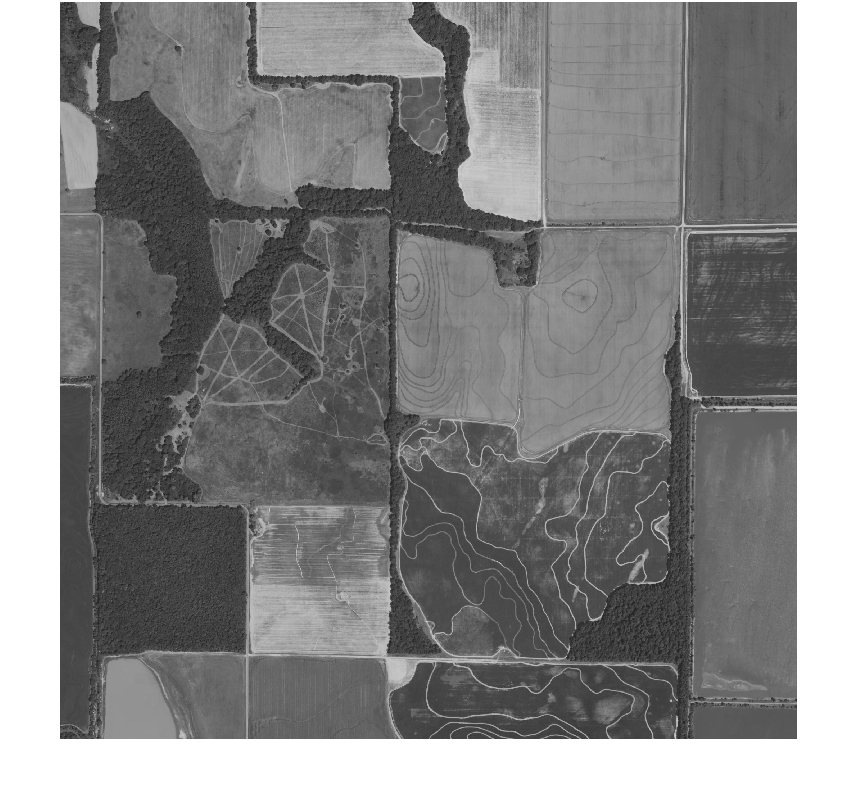

grayImage = im2gray(image); %Convert into gray scale
imshow(grayImage);

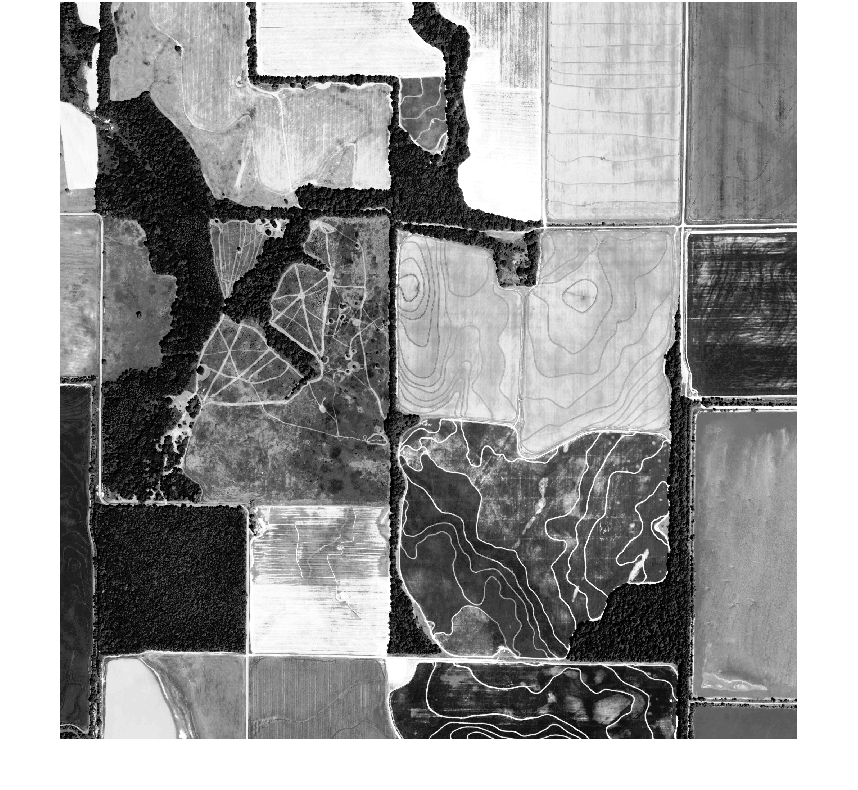

histeqImage = histeq(grayImage); %Apply histogram equalization
imshow(histeqImage);

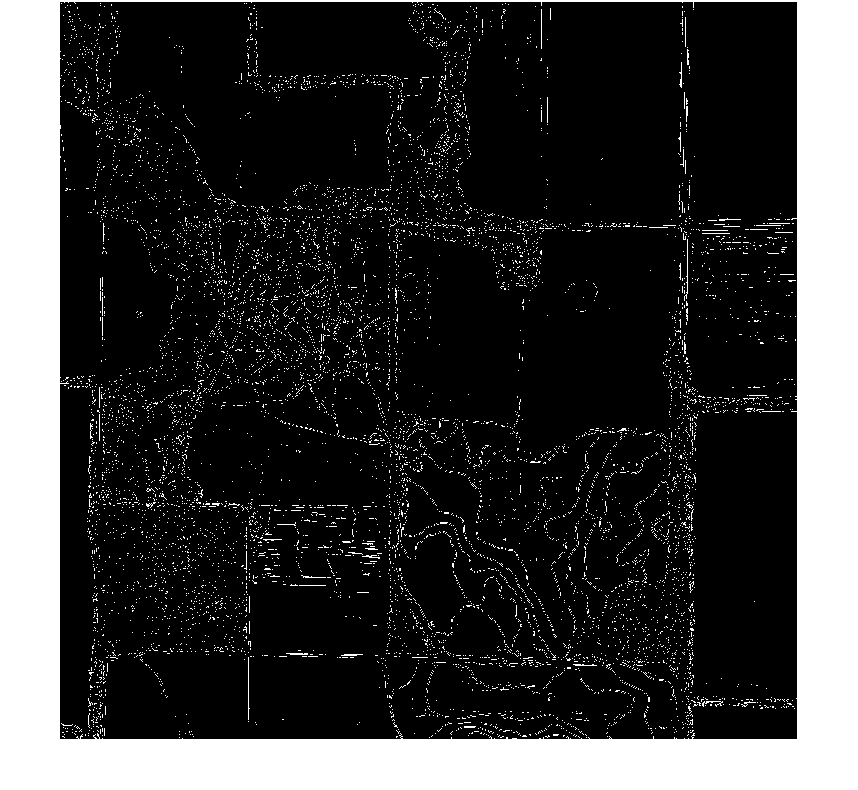

sobelImage = edge(histeqImage,"sobel"); %Apply Sobel Edge Detection
imshow(sobelImage);

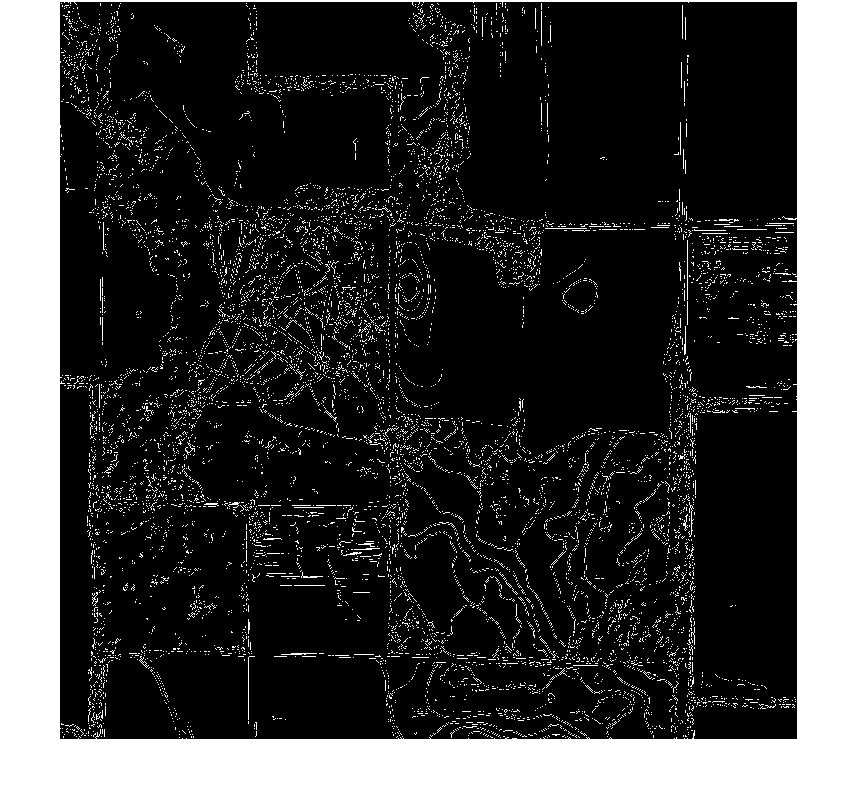

cannyImage = edge(histeqImage,"canny",0.25); %Apply Canny Detection
cannyImage2 = edge(grayImage,"canny");
imshow(cannyImage);

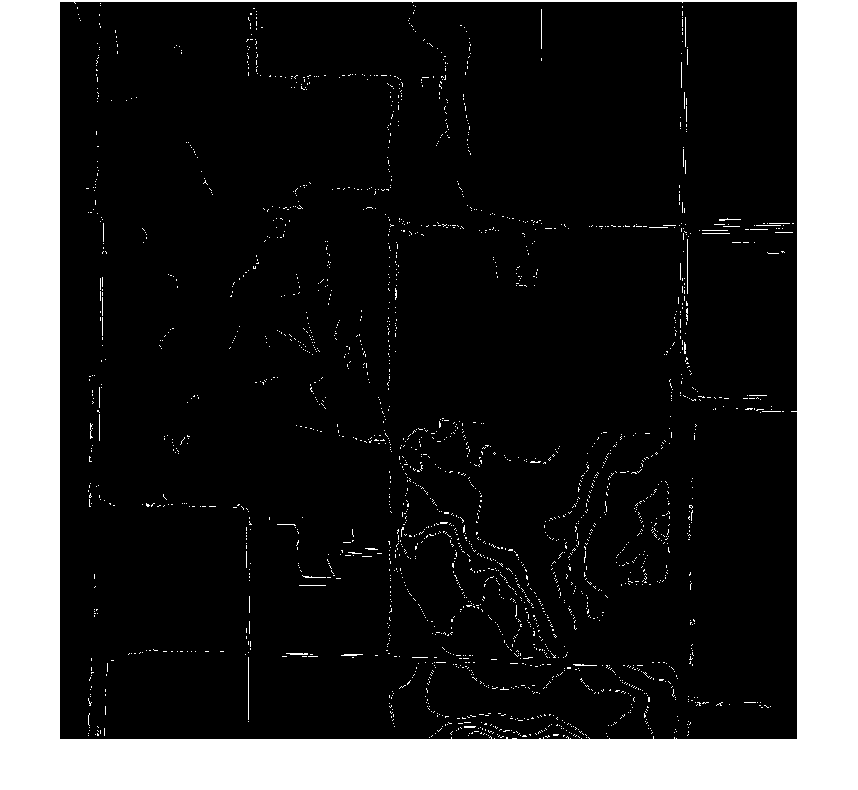

BW = bwareaopen(sobelImage,60); %Try morphological
imshow(BW);

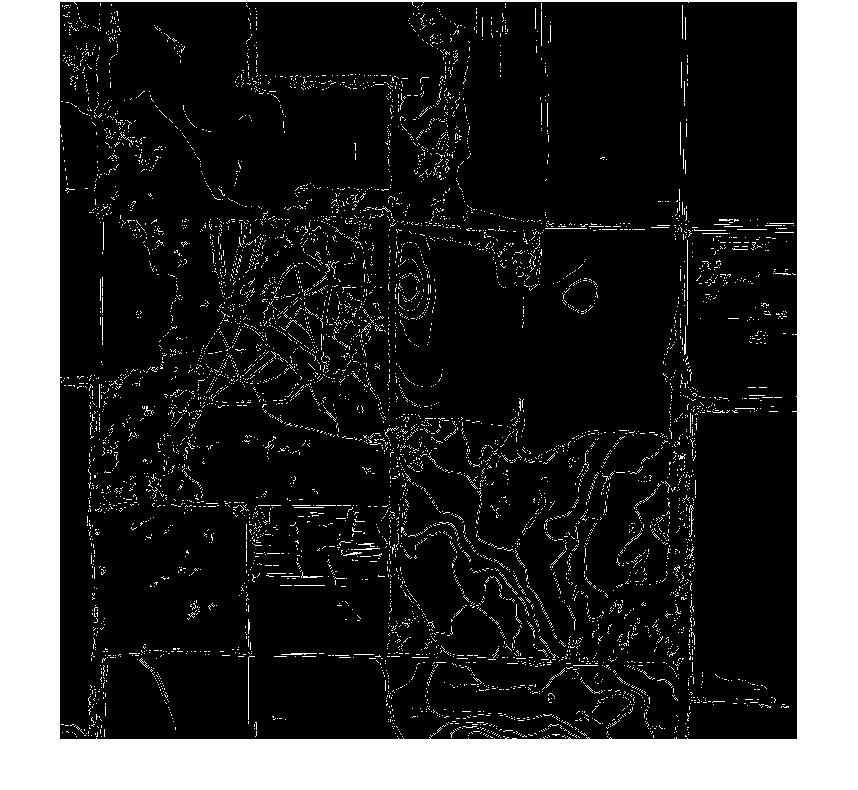

BW2 = bwareaopen(cannyImage,60);
imshow(BW2);

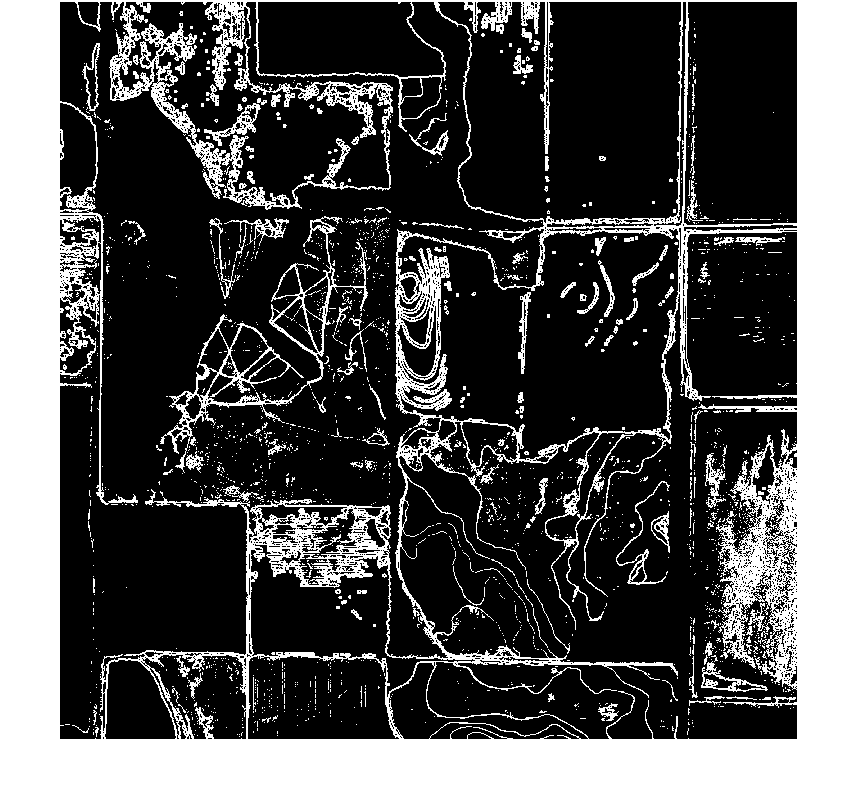

s=strel('disk',5,0); %Erode the image by structuring element 
%gray_Image = imresize(grayImage,0.5);
binaryImage = imbinarize(grayImage);
F=imerode(binaryImage,s);%Erode the image by structuring element
erodeImage=binaryImage-F;
imshow(erodeImage);

NumOfLines = 9

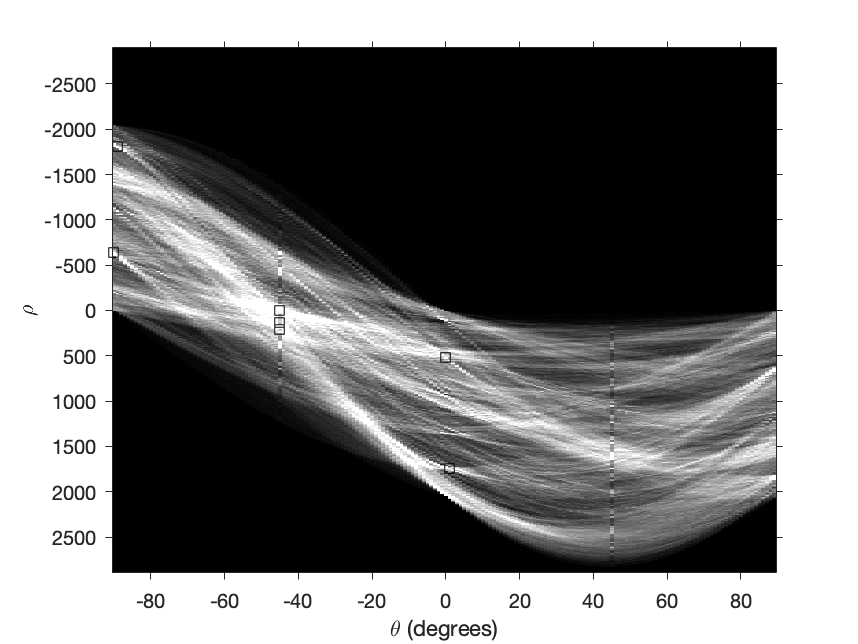

Fig =   Figure (38) with properties:

      Number: 38
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


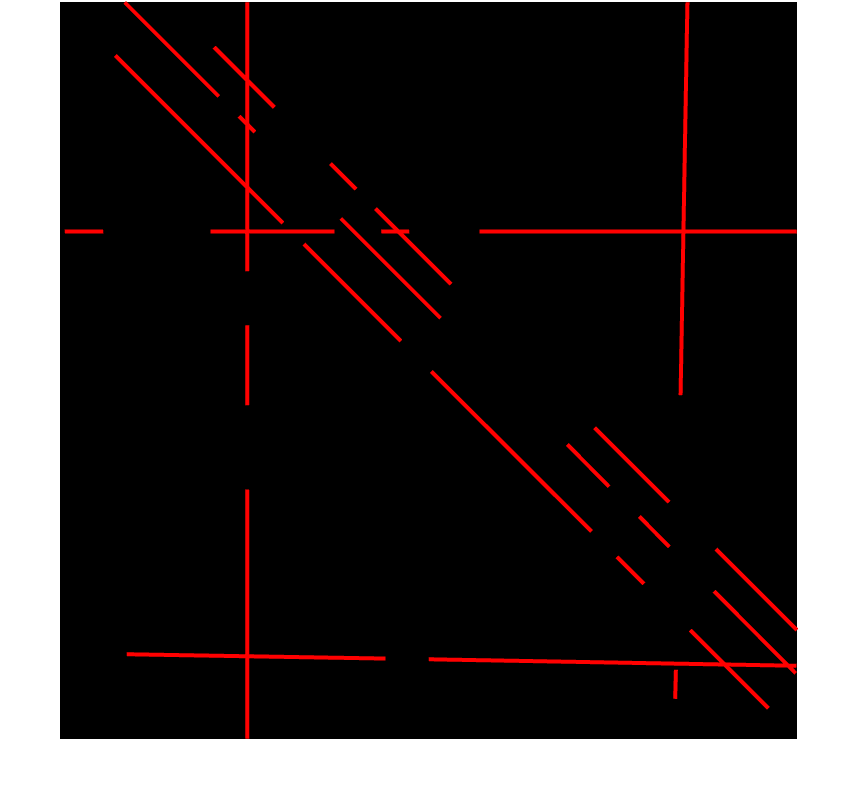

ht(erodeImage,grayImage);

function ht(erodeImage,grayImage)
[H, theta, rho] = hough(erodeImage);

% Show Hough space
figure,imshow(imadjust(rescale(H)), [], 'XData', theta, 'YData', rho, 'InitialMagnification', 'fit');
xlabel('\theta (degrees)'); ylabel('\rho');
axis on; axis normal; hold on;

%colormap(gca,gray);
%Assume we find four lines
NumOfLines=9 %try 4 and 10
P = houghpeaks(H, NumOfLines, 'threshold', ceil(0.69*max(H(:))));

%Superimpose a plot on the image of the transform that identifies the peaks
x = theta(P(:,2));
y = rho(P(:,1));
plot(x,y,'s','color','black');
lines = houghlines(erodeImage,theta,rho,P,'FillGap',75,'MinLength',50);
gh = zeros(2048,2048);
% Fig = figure, imshow(grayImage), hold on
Fig = figure, imshow(gh), hold on
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','red');
end
saveas(Fig,"full.jpg")
end
